# COVID-19 spread by region

## Data

regione="Sicilia";
data_location = urlwrite("https://raw.githubusercontent.com/pcm-dpc/COVID-19/master/dati-regioni/dpc-covid19-ita-regioni.csv","./dati_region.csv") ;
dati=readtable(data_location);
delete dati_region.csv

dati = dati(dati.denominazione_regione==regione, :);
dati = dati(:,{'data','totale_casi'});
dati.data = datetime(dati.data,"Format","uuuu-MM-dd'T'HH:mm:ss");
confirmed_cases = dati.totale_casi;



%START=6;
%CURRENT=START+length(confirmed_cases)-1;
%tbl=table(day,confirmed_cases);
%tbl.Properties.VariableNames{1}='Giorno';
%tbl.Properties.VariableNames{2}='Casi confermati';

disp(dati)

           data            totale_casi
    ___________________    ___________

    2020-02-24T18:00:00          0    
    2020-02-25T18:00:00          3    
    2020-02-26T18:00:00          3    
    2020-02-27T18:00:00          4    
    2020-02-28T18:00:00          4    
    2020-02-29T17:00:00          4    
    2020-03-01T17:00:00          9    
    2020-03-02T18:00:00          7    
    2020-03-03T18:00:00          7    
    2020-03-04T17:00:00         18    
    2020-03-05T17:00:00         18    
    2020-03-06T17:00:00         24    
    2020-03-07T18:00:00         35    
    2020-03-08T18:00:00         53    
    2020-03-09T18:00:00         54    
    2020-03-10T18:00:00         62    
    2020-03-11T17:00:00         83    
    2020-03-12T17:00:00        115    
    2020-03-13T17:00:00        130    
    2020-03-14T17:00:00        156    
    2020-03-15T17:00:00        188    
    2020-03-16T17:00:00        213

day_num = datenum(dati.data - dati.data(1));
CURRENT = day_num(end)

CURRENT = 20.9583

## Data fitting

[linfit, lin_r] = fit(day_num, confirmed_cases, 'poly1');
[expfit, exp_r] = fit(day_num, confirmed_cases, 'exp1');
[logfit, log_r] = logisticFit(day_num, confirmed_cases);

## Plotting

### Linear fitting

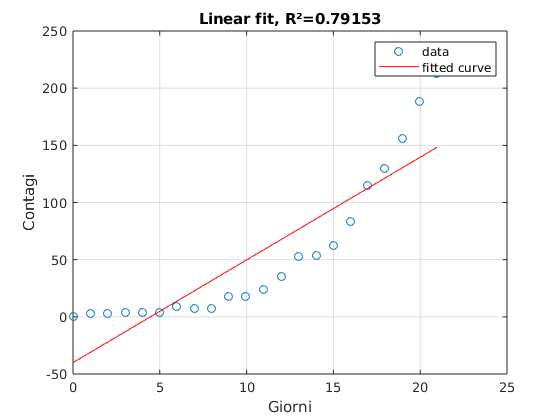

plot(linfit, day_num, confirmed_cases, "o")
grid on

title("Linear fit, R²="+lin_r.rsquare)
ylabel("Contagi")
xlabel("Giorni")


disp(linfit.p1+" nuovi contagi ogni giorno")

8.9826 nuovi contagi ogni giorno


disp("Predicted new cases for tomorrow: "+round(linfit(CURRENT+1)-confirmed_cases(end)))

Predicted new cases for tomorrow: -56


### Exponential fitting

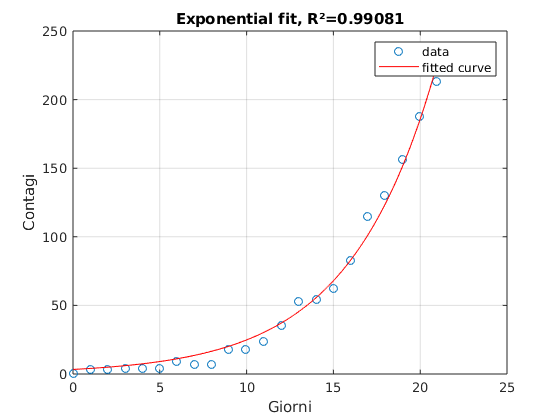

plot(expfit, day_num, confirmed_cases, "o")
grid on

title("Exponential fit, R²="+exp_r.rsquare)
ylabel("Contagi")
xlabel("Giorni")


disp("+"+expfit.b*100+"% nuovi contagi ogni giorno")

+20.1181% nuovi contagi ogni giorno


disp("Predicted new cases for tomorrow: "+round(expfit(CURRENT+1)-confirmed_cases(end)))

Predicted new cases for tomorrow: 63


## Logistic fitting

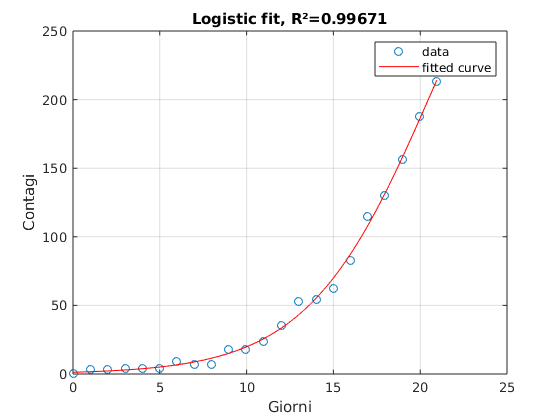

plot(logfit, day_num, confirmed_cases, "o")
grid on

title("Logistic fit, R²="+log_r.rsquare)
ylabel("Contagi")
xlabel("Giorni")


disp("Predicted new cases for tomorrow: "+round(logfit(CURRENT+1)-confirmed_cases(end)))

Predicted new cases for tomorrow: 30


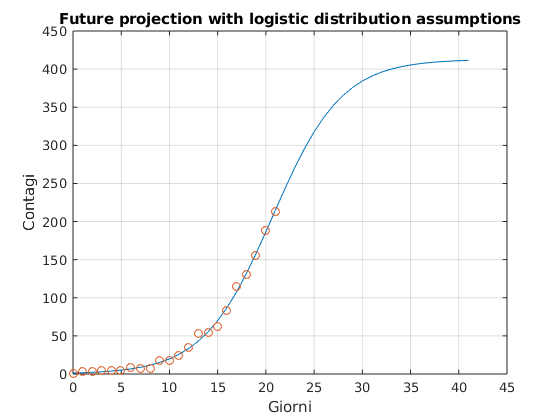

plot(0:(CURRENT+21),logfit(0:(CURRENT+21)))
grid on
title("Future projection with logistic distribution assumptions")
ylabel("Contagi")
xlabel("Giorni")

hold on
scatter(day_num,confirmed_cases)
hold off